clc
clear
addpath("../Data/")

% Dataset = load("Linearly_separable_dataset.mat")
Dataset = load("Incomplete_linear_separable_dataset.mat")

Dataset = 包含以下字段的 struct :
     test: [8000×3 double]
    train: [32000×3 double]


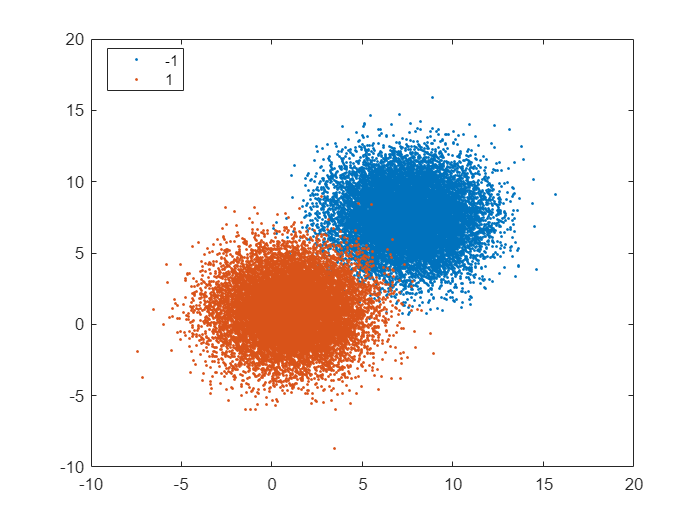

Train = Dataset.train(:,[1 2]);
Train = [Train,ones(size(Train,1),1)];
Train_label = Dataset.train(:,3);
Test = Dataset.test(:,[1,2]);
Test = [Test,ones(size(Test,1),1)];
Test_label = Dataset.test(:,3);



W = [randn(2,1);1];
% x = [-10,0.1,20];
% y = (-W(1,1)/W(2,1))*x-W(3,1)/W(2,1);
gscatter(Train(:,1),Train(:,2),Train_label)

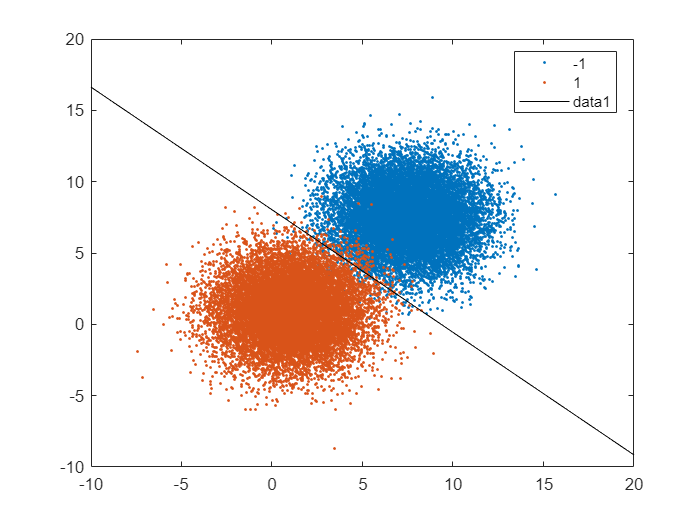

% hold on
% plot(x,y,"-b")

lr = 0.01;

epoch = 1000;

for i = 1:epoch

err = 0;
    for j = 1:1:size(Train,1)
        if Train(j,:)*W*Train_label(j)<0
            dw = - Train_label(j)*Train(j,:)';
            W = W - lr*dw;
            err = err+1;

        
        end
    end
if err == 0
    break
      
end
end
x = [-10,0.1,20];
y = -W(1)/W(2)*x-(W(3)/W(2));
gscatter(Train(:,1),Train(:,2),Train_label)
hold on
plot(x,y,"-k")
hold off

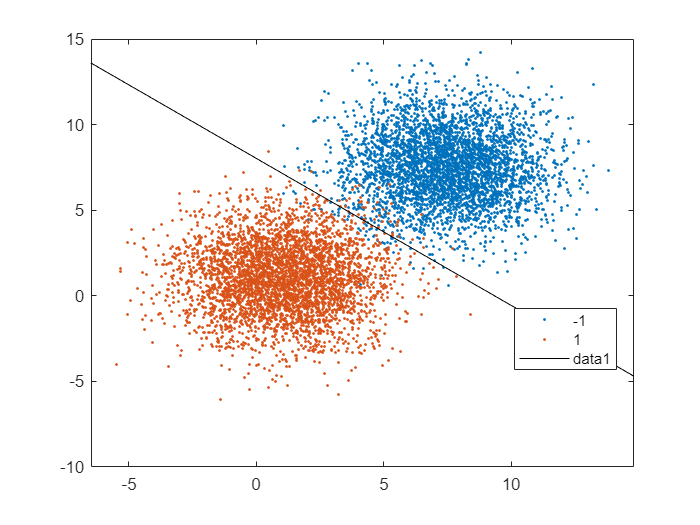

err_test = 0;
for k=1:1:size(Test_label,1)
if Test(k,:)*W*Test_label(k)<0

            err_test = err_test+1;
end
end
gscatter(Test(:,1),Test(:,2),Test_label)
hold on
plot(x,y,"-k")
hold off